# **Extracting useful signals from flawed sensor data: developing hybrid data-driven approaches with physical factors - Code Implementation **

**Cheng Yang (a), Glen T. Daigger (a), Evangelia Belia (b), B. Kerkez (a)**

**(a)** Civil and Environmental Engineering, University of Michigan, 2350 Hayward St, G.G. Brown Building, Ann Arbor, MI 48109, US  

**(b)** Primodal Inc., 145 Rue Aberdeen, Quebec City, Quebec, CA  

## About the research data

        The sensor signals in this study were $BOD_5$ concentration measurements of plant influent by a LiquID™ Station unit (ZAPS Technologies, LLC.), with 720 measurements per day. The dataset covered 688 days (495,360 measurements). Daily composite $BOD_5$  samples were also collected and analysed (688 days).  

        While the authors are not allowed to share meta-information of sensor data, we decided to anonymize all meta information but provided a data Matrix:

- **xBOD.m** - the data matrix storing the sensor signals used in this study. Preprossing was already done (replacing zeros with NaN), and the signal steam has been reshaped into a 688 by 720 matrix, where each row is an independent day and each column stands a measure at a time stamp starting from 6 am, with an interval of 2 minutes.    

- **data_label.m** - the label used in the section **Quality Classification**. 

### Import data 

clear; 
close all;

load('xBOD.mat');
load("data_label.mat");

## Figure 1 - Creation  

The indice of the days used for these plots are: 

(a) 27 ; (b) 3; (c) 10; (d) 65; (e) 50 ; (f) 73  

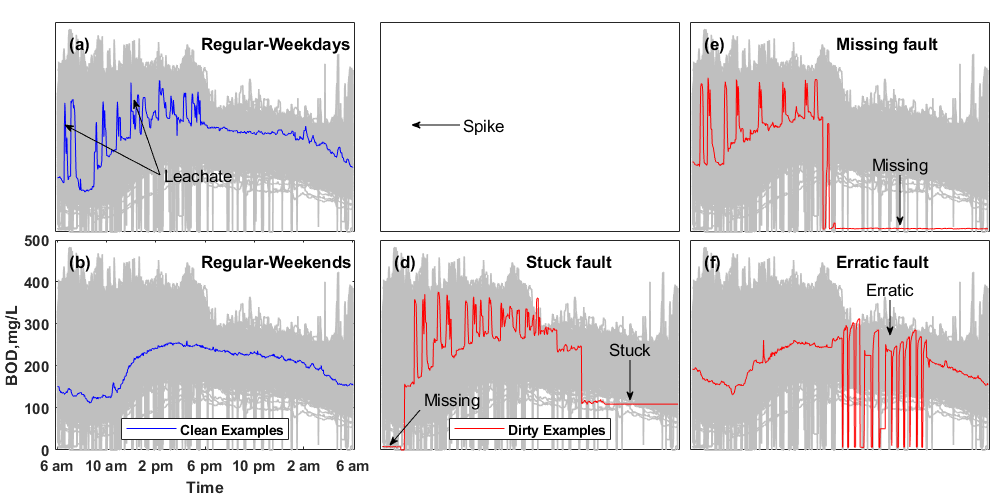

figure('position',[100 100 800 400],'Units','centimeters');
ax1 = axes('position',[0.055,0.535,0.30,0.42]); % Weekdays 
L1 = plot(xBOD(~data_label,:)','color',[0.75 0.75 0.75],'LineWidth',1);
ylim([0,500]);
xlim([-5,725]);
set(gca,'YTick',[],'XTick',[]);
hold on;
plt1= plot(xBOD(27,:),'-b');
text(gca,30,450,'(a)',"FontWeight","bold");
text(gca,350,450,'Regular-Weekdays',"FontWeight","bold");

hold off;

ax2 = axes('position',[0.38,0.535,0.3,0.42]);  %spike 
L2 = plot(xBOD(~data_label,:)','color',[0.75 0.75 0.75],'LineWidth',1);
ylim([0,500]);
xlim([-5,725]);
set(gca,'YTick',[],'XTick',[]);
hold on;
plot(xBOD(10,:),'-r');
text(gca,350,450,'Spike fault',"FontWeight","bold");
text(gca,30,450,'(c)',"FontWeight","bold");
hold off;

ax3 = axes('position',[0.69,0.535,0.3,0.42]); % Missing 
L3 = plot(xBOD(~data_label,:)','color',[0.75 0.75 0.75],'LineWidth',1);
ylim([0,500]);
xlim([-5,725]);
set(gca,'YTick',[],'XTick',[]);
hold on;
plot(xBOD(50,:),'-r');
text(gca,350,450,'Missing fault',"FontWeight","bold");
text(gca,30,450,'(e)',"FontWeight","bold");
hold off;

ax4 = axes('position',[0.055,0.10,0.3,0.42]); % Weekend 
L4 = plot(xBOD(~data_label,:)','color',[0.75 0.75 0.75],'LineWidth',1);
ylim([0,500]);
xlim([-5,725]);
set(gca,'XTick',linspace(0,720,7),'XTickLabel',{'6 am','10 am','2 pm','6 pm','10 pm','2 am','6 am'},...
    'FontWeight','bold');
xlabel('Time');
ylabel('BOD,mg/L');
hold on;
plot(xBOD(571,:),'-b');
text(gca,350,450,'Regular-Weekends',"FontWeight","bold");
text(gca,30,450,'(b)',"FontWeight","bold");
hold off;

ax5 = axes('position',[0.38,0.10,0.3,0.42]); % stuck 
L5 = plot(xBOD(~data_label,:)','color',[0.75 0.75 0.75],'LineWidth',1);
ylim([0,500]);
xlim([-5,725]);
set(gca,'YTick',[],'XTick',[]);
hold on;
plt2= plot(xBOD(65,:),'-r');
text(gca,350,450,'Stuck fault',"FontWeight","bold");
text(gca,30,450,'(d)',"FontWeight","bold");

hold off;

ax6 = axes('position',[0.69,0.10,0.3,0.42]); % erratic 
L6 = plot(xBOD(~data_label,:)','color',[0.75 0.75 0.75],'LineWidth',1);
ylim([0,500]);
xlim([-5,725]);
set(gca,'YTick',[],'XTick',[]);
hold on;
plot(xBOD(73,:),'-r');
text(gca,350,450,'Erratic fault',"FontWeight","bold");
text(gca,30,450,'(f)',"FontWeight","bold");
hold off;

legend(ax4,[plt1],'Clean Examples','location','south','FontWeight','bold');
legend(ax5,[plt2],'Dirty Examples','location','south','FontWeight','bold');
annotation('textarrow',[0.16 0.065],[0.65 0.75],'String','Leachate','HorizontalAlignment',"center",'HeadLength',5,"HeadWidth",5);
annotation('arrow',[0.16 0.134],[0.65 0.8],'HeadLength',5,"HeadWidth",5);
annotation('textarrow',[0.46 0.412],[0.75 0.75],'String','Spike','HorizontalAlignment',"center",'HeadLength',5,"HeadWidth",5);
annotation('textarrow',[0.9 0.9],[0.65 0.55],'String','Missing','HorizontalAlignment',"center",'HeadLength',5,"HeadWidth",5);
annotation('textarrow',[0.63 0.63],[0.28 0.2],'String','Stuck','HorizontalAlignment',"center",'HeadLength',5,"HeadWidth",5);
annotation('textarrow',[0.42 0.39],[0.18 0.11],'String','Missing','HorizontalAlignment',"center",'HeadLength',5,"HeadWidth",5);
annotation('textarrow',[0.89 0.89],[0.4 0.33],'String','Erratic','HorizontalAlignment',"center",'HeadLength',5,"HeadWidth",5);

clearvars -except data_label xBOD;

## Section 1: Pattern Separation 

### Failutre of traditional pattern separation algorithms (OLS + Lowpass filter + PCA)

***Oridnary Least Squares - using Fourier Series to approxiamte diurnal pattern ***

*An one-day series could be approximated as the sum of diurnal pattern and residuals, as *$y=\Gamma x+\epsilon \;$*, where the *$\Gamma x\;$*is the diurnal pattern, and *$\epsilon$* is the residuals. The formula could be further reduced into the matrix form as *


$$y=\Gamma x\;+\;\epsilon$$
 

*In the ordinary least squares, the objective is to mimimize the difference between *$y$* and *$\Gamma x\;$*, therefore, the loss function could be written as *


$$\hat{x} =\;\underset{x}{\arg \;\min } \;\left\|y-\Gamma x\right\|{\;}_2^{2\;} \;\;$$


*The diurnal term was approximated as the 3rd-order Fourier series,  *$y_i =x_1 +\sum_{k=1}^3 x_{2i\;} \cos \left(k\cdot w\cdot \;i\right)+\sum_{k=1}^3 x_{2\;i+1\;} \sin \left(k\cdot w\cdot \;i\right)\;+\epsilon_i$*, while in matrix form as *

$\begin{array}{l}
\left\lbrack \begin{array}{c}
y_1 \\
\vdots \\
y_i \\
\vdots \\
y_{720} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccccccc}
1 & \cos \left(1\cdot w\cdot 1\right) & \sin \left(1\cdot w\cdot 1\right) & \cos \left(2\cdot w\cdot 1\right) & \sin \left(2\cdot w\cdot 1\right) & \cos \left(3\cdot w\cdot 1\right) & \sin \left(3\cdot w\cdot 1\right)\\
\vdots  & \vdots  & \vdots  & \vdots  & \vdots  & \vdots  & \vdots \\
1 & \cos \left(1\cdot w\cdot i\right) & \sin \left(1\cdot w\cdot i\right) & \cos \left(2\cdot w\cdot i\right) & \sin \left(2\cdot w\cdot i\right) & \cos \left(3\cdot w\cdot i\right) & \sin \left(3\cdot w\cdot i\right)\\
\vdots  & \vdots  & \vdots  & \vdots  & \vdots  & \vdots  & \vdots \\
1 & \cos \left(1\cdot w\cdot 720\right) & \sin \left(1\cdot w\cdot 720\right) & \cos \left(2\cdot w\cdot 720\right) & \sin \left(2\cdot w\cdot 720\right) & \sin \left(3\cdot w\cdot 720\right) & \sin \left(3\cdot w\cdot 720\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
x_4 \\
x_5 \\
x_6 \\
x_7 
\end{array}\right\rbrack \\
\;
\end{array}$* + *$\left\lbrack \begin{array}{c}
\epsilon_1 \\
\vdots \\
\epsilon_i \\
\vdots \\
\epsilon_{720} 
\end{array}\right\rbrack \Rightarrow y=\Gamma x+\epsilon$ 

#### **Low pass filter**

filter= designfilt('lowpassiir','PassbandFrequency',2.5,...
    'StopbandFrequency',2.7,'PassbandRipple',0.05,...
    'StopbandAttenuation',60,'SampleRate',720,'DesignMethod','ellip');

#### Principal component analysis (Singular Value Decomposition with lower rank approximation) 

Using the first 5 principal components to approximate the diurnal patterns. Rank = 5.  

%% PCA 
[U,S,V] = svd(xBOD,'econ');
S(5:end,5:end) =0;
xBOD_pca = U*S*V';
clearvars -except data_label xBOD filter xBOD_pca;

#### Failure results presentation 

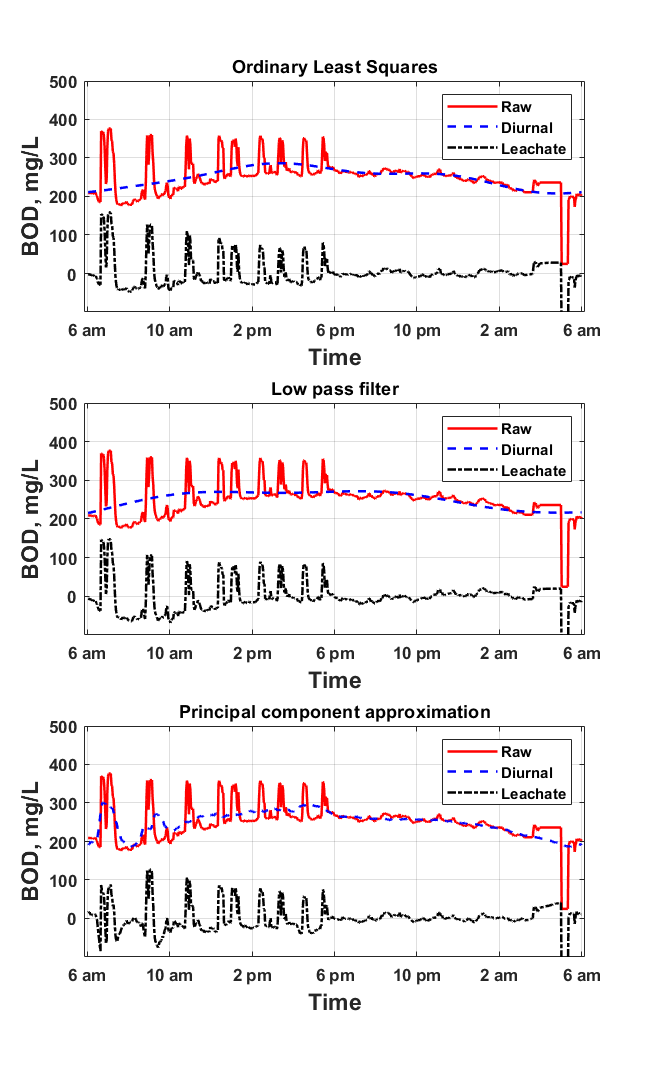

% Choose EXAMPLE idX
idx = 71; 

% OLS method 
% Set-up global constants  
d = 3;
ols_y = xBOD(idx,:)';
t = 1:length(ols_y);
w= 2*pi/720;
ols_y = xBOD(idx,:)';
ols_x = zeros(length(ols_y),2*d+1);
for  i = 1:d   
    ols_x(:,2*i) = cos(i*w*t);   
    ols_x(:,2*i+1) = sin(i*w*t);
end
ols_x(:,1) = ones(length(ols_y),1);
ols_beta = ols_x \ ols_y;



% plot the results 
figure('position',[0 0 600 1000],'Units','centimeters');

% OLS 
subplot(3,1,1)
ax1 = singleTSplot(ols_y);
hold on;
ax2 = plot(ols_x*ols_beta);
ax3 = plot(ols_y - ols_x*ols_beta);
set(ax1,'color','red','LineWidth',1.5);
set(ax2,'color','blue','LineWidth',1.5,'LineStyle','--');
set(ax3,'color','black','LineWidth',1.5,'LineStyle','-.');
hold off;
legend('Raw','Diurnal','Leachate');    
title('Ordinary Least Squares')

% low pass filter  
subplot(3,1,2)
ax1 = singleTSplot(xBOD(idx,:));
hold on;

filter_y = filtfilt(filter,xBOD(idx,:)');
ax2 = plot(filter_y);
ax3 = plot(xBOD(idx,:)' - filter_y);

set(ax1,'color','red','LineWidth',1.5);
set(ax2,'color','blue','LineWidth',1.5,'LineStyle','--');
set(ax3,'color','black','LineWidth',1.5,'LineStyle','-.');
title('Low pass filter')
hold off;
legend('Raw','Diurnal','Leachate');  
% PCA/SVD  
subplot(3,1,3)
ax1 = singleTSplot(xBOD(idx,:));
hold on;
ax2 = plot(xBOD_pca(idx,:));
ax3 = plot(xBOD(idx,:) - xBOD_pca(idx,:));

set(ax1,'color','red','LineWidth',1.5);
set(ax2,'color','blue','LineWidth',1.5,'LineStyle','--');
set(ax3,'color','black','LineWidth',1.5,'LineStyle','-.');
title('Principal component approximation')
hold off;
legend('Raw','Diurnal','Leachate');  

### Customized algorithms coupled with physcial factors - regularized least squares 

**Important Note:**

- Processing through the whole daily profiles takes more than 3 hours, therefore, processed results are already uploaded in this repo for time saving.

- The implementation of the pattern separation process can be tracked in:  seperatePatterScript.m. Details about its relating functions such as seperatePattern,m, hhlsngd.m, hubhin.m and dhubhin could be found in README.md 

**Math behind: **

**Regularized Least Squares - Shifted Huber-Hinge Regularization( Non-negtaive Regularization)**

An one-day series could be approximated as the sum of diurnal pattern, leachate and residuals, as $y=\Gamma x+s+\epsilon \;$, where the $\Gamma x\;$is the diurnal pattern, the $s$ is the leachate pattern and $\epsilon$ is the residuals. The formula could be further reduced into the matrix form as 


$$y=\Gamma x+\textrm{Is}+\epsilon =\left\lbrack \begin{array}{cc}
\Gamma \; & I
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
s
\end{array}\right\rbrack +\epsilon =\tilde{A} \;\tilde{x} +\epsilon$$
 

Where $I$ is the Identity matrix, and $\tilde{A} \;$is the horizontal concatenation of $\Gamma$ and $I$, and $\tilde{x}$ is the vertical concatenation of $x$ and $s$. Simliarly, this problem has been transfromed  into 

$\hat{x} =\;\underset{x}{\arg \;\min } \;\left\|y-\Gamma x-s\right\|{\;}_2^{2\;} =\underset{\tilde{x} }{\arg \;\min } \;\left\|y-\tilde{A} \tilde{x} \right\|{\;}_2^2 \;$. 

This time, regularization was changed and was applied on the leachate term, $s$,  as 


$$\hat{x} =\;\underset{x}{\arg \;\min } \;{\left\|y-\Gamma x-s\;\right\|}_2^2 \;+\lambda \cdot h\left(s\right)\;$$


The lechate pattern is regularized by the shifted huber-hinger error function$\;h\left(x\right)$, which penalizes the negative part. The shifted huber-hinger error function is: $h\left(x\right)=\left\lbrace \begin{array}{cc}
-x-\frac{\;\delta }{2} & x\le -\delta \\
\;\;\frac{1}{2\delta }x^2  & -\delta <x\le 0\;\\
0 & x>0
\end{array}\right.\;$ and its derivative is:   $\frac{\mathrm{d}}{\mathrm{d}x}h\left(x\right)=\left\lbrace \begin{array}{cc}
-1 & x\le -\delta \\
\;\;\frac{1}{\delta }x & -\delta <x\le 0\;\\
0 & x>0
\end{array}\;\right.$  .The shape of these two functions are displayed below. 

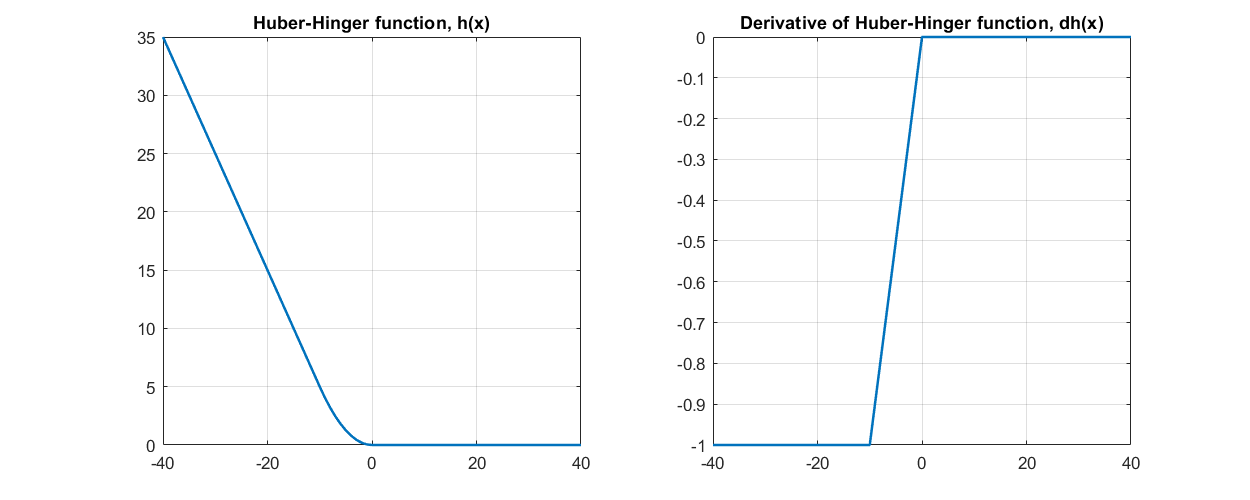

% plotting hubhin() and dhubhin() 
figure('position',[0 0 1000 400],'Units','centimeters');
subplot(1,2,1);
plot(-40:40,hubhin(-40:40,10),'-','LineWidth',1.5);
grid on;
title('Huber-Hinger function, h(x)')
subplot(1,2,2);
plot(-40:40,dhubhin(-40:40,10),'-','LineWidth',1.5);
grid on;
title('Derivative of Huber-Hinger function, dh(x)')

### Figure 1 - Creation  